supressed_print= evalc('run Term_Project_Live_Script.mlx');

clear supressed_print

sympref('FloatingPoint',true);

# EE514 Advanced Topics in Automatic Control

# Term Project Report Draft, Part 2

Dominic Riccoboni

## S and S_dot

### Along Switching Surface, System is Linear and Reduced Order

Define a switching surface $s(\overset{\rightharpoonup}{x})$

syms lambda v_hat_m v_ms

s_eqn = theta_dot + lambda*theta == 0

$$s\_eqn = \lambda \,\theta +\dot{\theta }=0$$

Its derivative is $\dot{s}(\overset{\rightharpoonup}{x})$

s_dot_eqn = theta_ddot + lambda*theta_dot == 0

$$s\_dot\_eqn = \ddot{\theta }+\lambda \,\dot{\theta }=0$$

Substitute the dynamics of the system in through $\ddot\theta$

s_dot_eqn = subs(s_dot_eqn, theta_ddot, subs(rhs(isolate(ModPendulumEOM , theta_ddot)),v_m, v_hat_m))

$$s\_dot\_eqn = \frac{T_{\mathrm{ba}}\,\mathrm{sign}\left(\dot{\theta }\right)+\frac{K_{c}\,{\hat{v}}_{m}}{R_{a}}+L\,M\,g\,\sin\left(\theta \right)-\frac{K_{c}\,N\,\dot{\theta }}{K_{m}\,R_{a}}}{J_{m}\,N+J_{p}}+\lambda \,\dot{\theta }=0$$

Where $\hat{v}_m$ is the feecback that nullfies $\dot{s}(\overset{\rightharpoonup}{x})$

v_hat_m_eqn(theta_dot,theta)  = v_hat_m == rhs(isolate(s_dot_eqn, v_hat_m))

$$v\_hat\_m\_eqn(theta\_dot, theta) = {\hat{v}}_{m}=-\frac{R_{a}\,\left(\lambda \,\dot{\theta }+\frac{T_{\mathrm{ba}}\,\mathrm{sign}\left(\dot{\theta }\right)+L\,M\,g\,\sin\left(\theta \right)-\frac{K_{c}\,N\,\dot{\theta }}{K_{m}\,R_{a}}}{J_{m}\,N+J_{p}}\right)\,\left(J_{m}\,N+J_{p}\right)}{K_{c}}$$

Check that the algebra was correct

simplify(subs(ModPendulumEOM, v_m, rhs(v_hat_m_eqn)))

$$ans = \ddot{\theta }+\lambda \,\dot{\theta }=0$$

## Nullifying Feedback

Substitute in system parameters to $\hat{v}_m$

v_hat_m_eqn(theta_dot,theta, lambda) = subs(v_hat_m_eqn, [L, M, g, J_m, J_p, N, K_m, T_ba]...
    ,[L_n, M_n, g_n, Jm, Jp, N_n, Km, T_ba_n]);
v_hat_m_eqn(theta_dot,theta, lambda) = subs(v_hat_m_eqn, K_c/R_a,  KcRa)

$$v\_hat\_m\_eqn(theta\_dot, theta, lambda) = {\hat{v}}_{m}=0.3501\,\dot{\theta }-1.0684\,\mathrm{sign}\left(\dot{\theta }\right)-0.6600\,\sin\left(\theta \right)-0.1144\,\lambda \,\dot{\theta }$$

Create a function handle from the symbolic $\hat{v}_m$

vhatm_fun = matlabFunction(rhs(v_hat_m_eqn))

vhatm_fun = function_handle with value:
    @(theta_dot,theta,lambda)theta_dot.*3.501492444538253e-1-sign(theta_dot).*1.068443539558041-sin(theta).*6.6e-1-lambda.*theta_dot.*1.143997714867024e-1


% x0 = [deg2rad(110), 0]';
% vhatm_fun(x0(1), x0(2),100)

Choose a numerical root for $s(\overset{\rightharpoonup}{x})$

% lambda_n = 45;
% 
% %Set initial conditions to zero velocity and theta of 110 degrees
% x0 = [deg2rad(110), 0]';
% tsim = 100;
% 
% NLout = sim('Motorized_Pendulum_VSC');
% 
% 
% %Plot the results
% figure
% subplot(3,1,1)
% plot(NLout.tout,rad2deg(NLout.x(:,1)), [0 NLout.tout(end)], [0 0], '--' )
% xlabel('time [s]')
% ylabel('\theta [deg]')
% title('Nonlinear Response 2, Iterated LQR Gains')
% 
% subplot(3,1,2)
% plot(NLout.tout,rad2deg(NLout.x(:,2)), 'g')
% xlabel('time [s]')
% yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
% set(yl_1, 'Interpreter', 'latex');
% 
% 
% subplot(3,1,3)
% plot(NLout.tout,NLout.vm, 'r')
% xlabel('time [s]')
% ylabel('v_m [V]')
% set(gcf,'position',[0,0,800,900]);


## Derive Switching Law $v_{m,s}$ and Simulate Response

K = 10;
lambda_n = 45;

v_ms_eqn = v_ms == rhs(v_hat_m_eqn) - K*sign(lhs(s_eqn))

$$v\_ms\_eqn(theta\_dot, theta, lambda) = v_{\mathrm{ms}}=0.3501\,\dot{\theta }-10\,\mathrm{sign}\left(\lambda \,\theta +\dot{\theta }\right)-1.0684\,\mathrm{sign}\left(\dot{\theta }\right)-0.6600\,\sin\left(\theta \right)-0.1144\,\lambda \,\dot{\theta }$$


%Set initial conditions to zero velocity and theta of 110 degrees
x0 = [deg2rad(110), 0]';
tsim = 5;
fric_mod = 1; %Select 1 - couloumb friction with damping and no boundary layer
              %Select 2 - coulomb friction with damping and a smoothing boundary layer
switch_law = 3; %Select 1 - signum switching law
                %Select 2 - smoothing saturation switching law (boundary layer)
                %Select 3 - smoothing error function switching law - boundary layer

err_fnc_coeff = 0.9; %error function switching law steepness coefficient
t_samp = 1/100; %Sample time for the sensors
NLout1 = sim('Motorized_Pendulum_VSC');



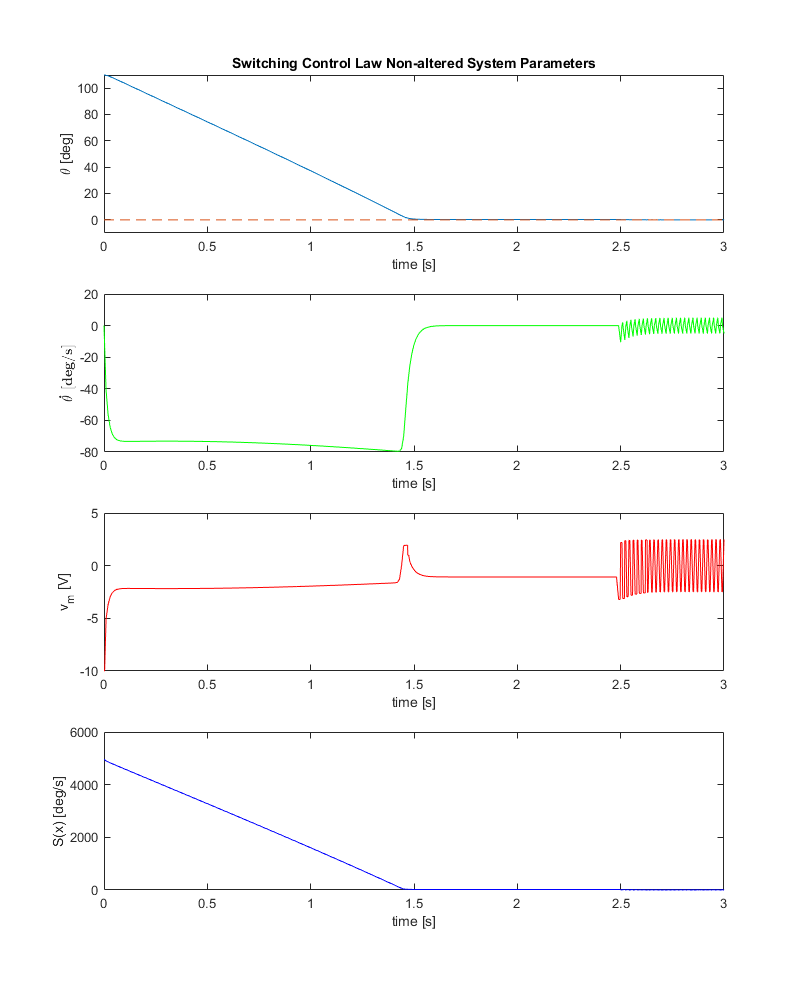

%Plot the results
figure
ax1 = subplot(4,1,1);
plot(NLout1.tout,rad2deg(NLout1.x(:,1)), [0 NLout1.tout(end)], [0 0], '--' )
xlabel('time [s]')
ylabel('\theta [deg]')
title('Switching Control Law Non-altered System Parameters')
ylim([-10 max(rad2deg(NLout.x(:,1)))])
xlim([0 3])

ax2 = subplot(4,1,2);
plot(NLout1.tout,rad2deg(NLout1.x(:,2)), 'g')
xlabel('time [s]')
yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
set(yl_1, 'Interpreter', 'latex');
xlim([0 3])

ax3 = subplot(4,1,3);
plot(NLout1.tout,NLout1.vm, 'r')
xlabel('time [s]')
ylabel('v_m [V]')
xlim([0 3])

ax4 = subplot(4,1,4);
plot(NLout1.tout,rad2deg(NLout1.S), 'bl')
xlabel('time [s]')
ylabel('S(x) [deg/s]')
linkaxes([ax1,ax2, ax3, ax4],'x');
xlim([0 3])
set(gcf,'position',[0,0,800,1000]);

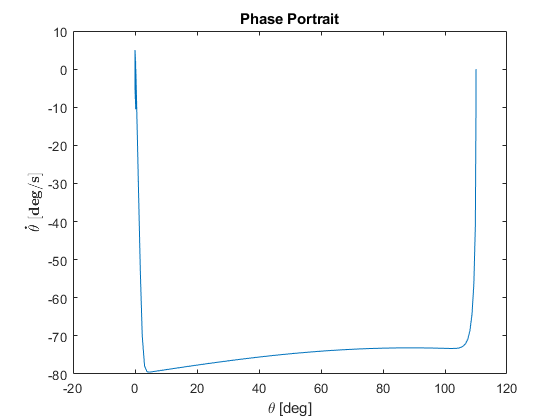


figure
plot(rad2deg(NLout1.x(:,1)), rad2deg(NLout1.x(:,2)))
xlabel('\theta [deg]')
yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
set(yl_1, 'Interpreter', 'latex');
title('Phase Portrait')

## Test Controller Out on Parametrically Different System

### Generate Statistical Spread in System Parameters

[L_n, M_n, Jm, Jp, Km, T_ba_n].'

ans =     0.3565
    0.0269
    0.0011
    0.0017
   22.3648
    0.1445



uncertainty_ratio = 0.3;
param_scale = ones(6,1) + uncertainty_ratio*(rand(6,1)-.5);

L_n = param_scale(1)*L_n

L_n = 0.3121

M_n = param_scale(2)*M_n

M_n = 0.0261

Jm = param_scale(3)*Jm

Jm = 9.9765e-04

Jp = param_scale(4)*Jp

Jp = 0.0019

Km = param_scale(5)*Km

Km = 21.9046

T_ba_n = param_scale(6)*T_ba_n

T_ba_n = 0.1623

### Simulate the Switching Controller With New Parameters

%Set initial conditions to zero velocity and theta of 110 degrees
x0 = [deg2rad(110), 0]';
tsim = 5;
fric_mod = 1; %Select 1 - couloumb friction with damping and no boundary layer
              %Select 2 - coulomb friction with damping and a smoothing boundary layer
switch_law = 3; %Select 1 - signum switching law
                %Select 2 - smoothing saturation switching law (boundary layer)
                %Select 3 - smoothing error function switching law - boundary layer

err_fnc_coeff = 0.9; %error function switching law steepness coefficient
t_samp = 1/100; %Sample time for the sensors
NLout2 = sim('Motorized_Pendulum_VSC');



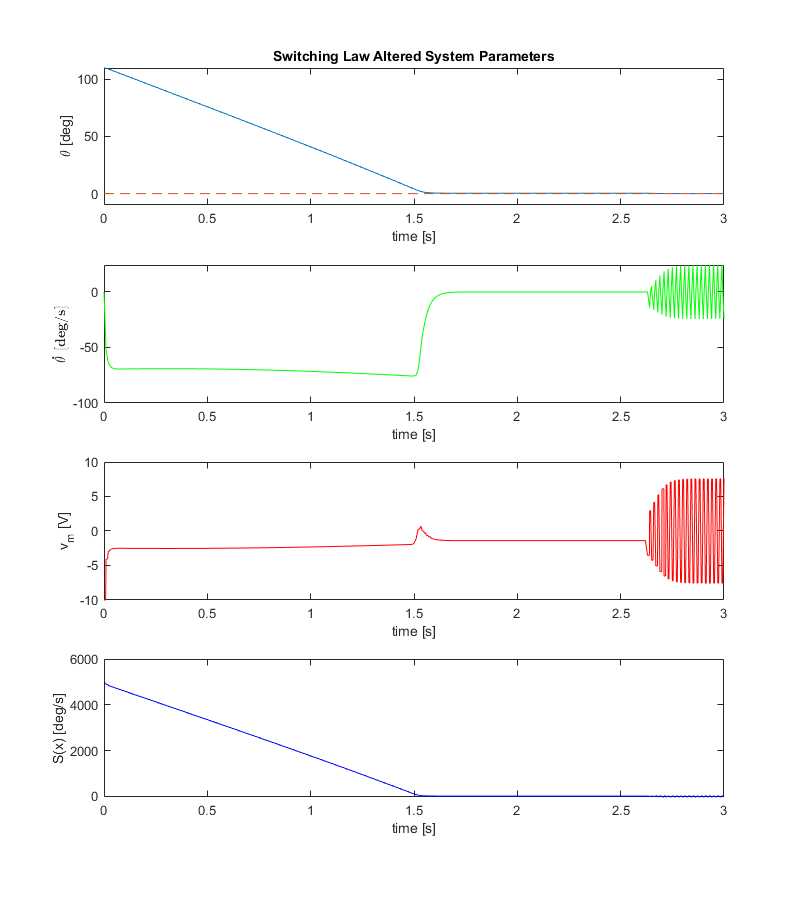

%Plot the results
figure
ax1 = subplot(4,1,1);
plot(NLout2.tout,rad2deg(NLout2.x(:,1)), [0 NLout2.tout(end)], [0 0], '--' )
xlabel('time [s]')
ylabel('\theta [deg]')
title('Switching Law Altered System Parameters')
ylim([-10 max(rad2deg(NLout.x(:,1)))])
xlim([0 3])

ax2 = subplot(4,1,2);
plot(NLout2.tout,rad2deg(NLout2.x(:,2)), 'g')
xlabel('time [s]')
yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
set(yl_1, 'Interpreter', 'latex');
xlim([0 3])

ax3 = subplot(4,1,3);
plot(NLout2.tout,NLout2.vm, 'r')
xlabel('time [s]')
ylabel('v_m [V]')
xlim([0 3])

ax4 = subplot(4,1,4);
plot(NLout2.tout,rad2deg(NLout2.S), 'bl')
xlabel('time [s]')
ylabel('S(x) [deg/s]')
linkaxes([ax1,ax2, ax3, ax4],'x');
xlim([0 3])
set(gcf,'position',[0,0,800,900]);

%Plot the new phase portrait
figure
plot(rad2deg(NLout1.x(:,1)), rad2deg(NLout1.x(:,2)))
xlabel('\theta [deg]')
yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
set(yl_1, 'Interpreter', 'latex');
title('Phase Portrait')